clear; close; clc;
W = 700*9.81; % weight in Newtons
W2S = 500; % wing loading in newtons per square meter


A = 29; % aspect ratio


s_i = 3; % inboard section semispan
s_o = 7; % outbaord section span
lambda = .4; % taper ratio of equivalent wing
lambda_i = 1; % imboard taper ratio

S = W/W2S

S = 13.7340

b = sqrt(A*S)

b = 19.9571

c_bar = S/b % average cord

c_bar = 0.6882

A = b/c_bar

A = 29


lambda_o = (lambda*(s_o+s_i) - s_i*lambda_i) / s_o

lambda_o = 0.1429


c_bar_i = c_bar * (s_i+s_o) / (s_i + 2/3 * s_o * (1 + lambda_o + lambda_o^2) / (1+lambda_o))

c_bar_i = 0.8880


c_bar_o = 2/3 * c_bar_i * (1 + lambda_o + lambda_o^2) / (1+lambda_o)

c_bar_o = 0.6026


c_t = c_bar_i*lambda_o

c_t = 0.1269



% layout locations for points
% xcoordinate of points
x_coords = [0, s_o, b/2, b/2, s_o, 0] % LE inboard center,  LE joint location, LE outboard tip, TE inboard center,  TE joint location, TE outboard tip

x_coords =          0    7.0000    9.9786    9.9786    7.0000         0


% ycoordingates of points
y_coords = [0, 0, 0, -c_t, -c_bar_o, -c_bar_o]

y_coords =          0         0         0   -0.1269   -0.6026   -0.6026


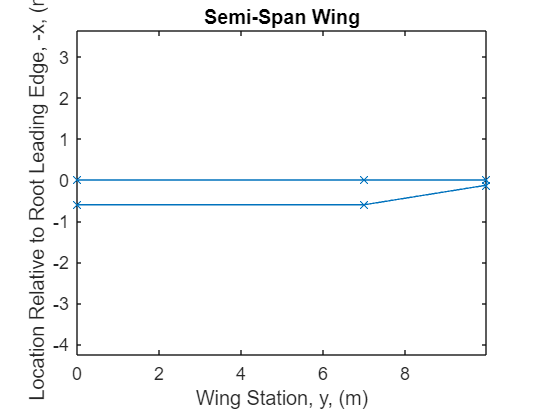


% plot wings
figure;

plot(x_coords, y_coords, "-x");
title("Semi-Span Wing"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;

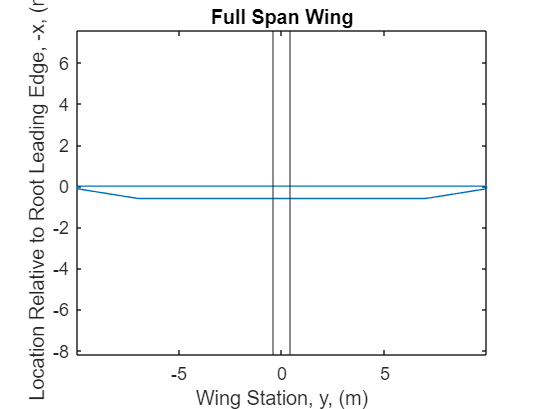


figure;
plot([x_coords, -fliplr(x_coords)], [y_coords,fliplr(y_coords)])
title("Full Span Wing"); xlabel("Wing Station, y, (m)"); ylabel("Location Relative to Root Leading Edge, -x, (m)");
axis equal;

xline(.4,"-");
xline(-.4,"-")